%{ 
Una empresa fabrica dos tipos de cajas ecológicas: modelo A y modelo B.
Cada tipo requiere materiales y tiempo de máquina diferentes.

Cada caja A requiere:

2 unidades de cartón

3 horas de máquina

Cada caja B requiere:

4 unidades de cartón

2 horas de máquina

La empresa tiene disponibles:

100 unidades de cartón

90 horas de máquina

Los beneficios por cada unidad vendida son:

Caja A: 6 €

Caja B: 8 €

Además:

Solo se pueden producir cantidades enteras de cajas.

La empresa debe fabricar al menos 10 cajas en total (A + B ≥ 10).

No puede fabricar más de 30 cajas de tipo B por semana.
%}

%Codigo para realizar programación lineal

 %Datos del problema
    % X1 = Cajas A por semana ; X2 = Cajas B por semana
    % Función Objetivo --> Z= 6X1 + 8X2 ;Maximizar el beneficio
    % Restricciones:
    %2X1 + 4X2 <=100 Carton Disponible
    %3X1 + 2X2 <=90 Horas Maquina
    % X1 + X2 >=10 Debe fabricar como minimo
    % X2 <=30 Limite cajas B por semana
    %X1,X2 >=0
Z = [-6 -8]; % Coeficientes para maximizar z, intlinprog minimiza, por eso signo negativo
A = [2 4; 3 2; -1 -1; 0 1];
b = [100; 90; -10; 30];
lb = [0 0];
intcon = [1 2]; % Variables enteras


% Resolver problema entero
[x, fval, exitflag] = intlinprog(Z, intcon, A, b, [], [], lb, []);

Running HiGHS 1.7.0: Copyright (c) 2024 HiGHS under MIT licence terms
Coefficient ranges:
  Matrix [1e+00, 4e+00]
  Cost   [6e+00, 8e+00]
  Bound  [0e+00, 0e+00]
  RHS    [1e+01, 1e+02]
Presolving model
3 rows, 2 cols, 6 nonzeros  0s
3 rows, 2 cols, 6 nonzeros  0s
Objective function is integral with scale 0.5

Solving MIP model with:
   3 rows
   2 cols (0 binary, 2 integer, 0 implied int., 0 continuous)
   6 nonzeros

        Nodes      |    B&B Tree     |            Objective Bounds              |  Dynamic Constraints |       Work      
     Proc. InQueue |  Leaves   Expl. | BestBound       BestSol              Gap |   Cuts   InLp Confl. | LpIters     Time

         0       0         0   0.00%   -380            inf                  inf        0      0      0         0     0.0s

Solving report
  Status            Optimal
  Primal bound      -240
  Dual bound        -240
  Gap               0% (tolerance: 0.01%)
  Solution status   feasible
                    -240 (objective)
        


if exitflag == 1
    fprintf('Solución óptima encontrada:\n');
    fprintf('x1 = %.0f\n', x(1));
    fprintf('x2 = %.0f\n', x(2));
    fprintf('Valor óptimo z = %.2f\n', -fval);
else
    disp('No se encontró solución óptima.');
end

Solución óptima encontrada:


x1 = 20


x2 = 15


Valor óptimo z = 240.00


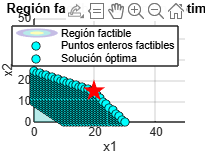


%Plotear la solución graficamente
% Crear rejilla para graficar la región factible
[x1, x2] = meshgrid(0:2:50, 0:2:50);

% Restricciones
r1 = 2*x1 + 4*x2 <=100;
r2 = 3*x1 + 2*x2 <=90;
r3 = -x1 + -x2 <=-10;
r4 = x2 <=30;
regionFactible = r1 & r2 & r3 & r4;

% Graficar región factible
figure;
hold on;
contourf(x1, x2, regionFactible, [1 1], 'LineColor', 'none', 'FaceAlpha', 0.3);
xlabel('x1');
ylabel('x2');
title('Región factible y solución óptima');
grid on;

% Graficar puntos enteros factibles
for i=0:floor(max(x1(:)))
    for j=0:floor(max(x2(:)))
        if (2*i + 4*j <=100) && (3*i + 2*j <=90) && (-i + -j <=-10) && (j <=30)
            plot(i,j,'ko','MarkerFaceColor','cyan');
        end
    end
end

% Graficar solución óptima
plot(x(1), x(2), 'rp', 'MarkerSize', 15, 'MarkerFaceColor', 'red');
legend('Región factible', 'Puntos enteros factibles', 'Solución óptima');
hold off;